# Introduction to state space modeling

## The need for state space methods

The first step in the control design process is to develop appropriate mathematical models of the system to be controlled. So far in this course, we have seen the use of transfer functions to model systems. But transfer functions have  their limitations.

### Limitations of input-output relationsthips

Transfer functions only provide a ratio of output to input and often miss internal state details that can be critical for understanding system dynamics and control. For example, consider the following RLC cirtuit.

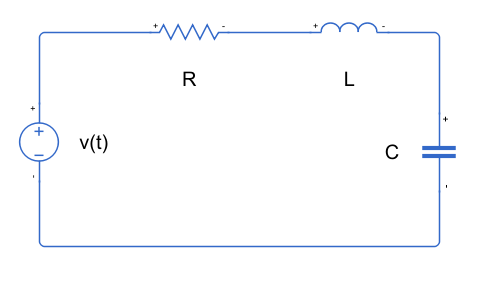

For a series RLC circuit driven by a voltage source $v(t)$, the governing differential equation based on Kirchhoff's voltage law can be expressed as:


$$$ v(t) = Ri(t) + L\frac{di(t)}{dt} + \frac{1}{C}\int_0^t{i(\tau)d\tau} $ $$


assuming zero initital conditions. If our output (measurement) is the current $i(t)$, then the transfer function is given as 


$$H(s) = \frac{I(s)}{V(s)} = \frac{1}{R + sL + \frac{1}{sC}} = \frac{sC}{LC s^2+ RC s + 1}$$


Limitations: 

- Important information such as the energy stored in the inductor and the capacitor at any given time, which are crucial for understanding the transient behavior of the circuit, are not visible in the transfer function.

- Transfer functions are valid only for linear time invariant systems. 

- The transfer function is derived from the perspective of a given measurement. But we should be able the describe the system independently of any measurements, like the differential equaiton does. 

### Concept of state

There are two energy storage devices in the circuit, the inductor and the capacitor. The energy stored in the inductor is given as 


$$E_L(t) = \frac{1}{2} L i^2(t)$$


and that in the capacitor is given as 


$$$E_C(t) = \frac{1}{2} \frac{q^2(t)}{C} $ $$


where $q(t) = \int{i(\tau)d\tau$ is the charge stored in the capacitor. Then, if we define the "state" of the circuit using the vector


$$\mathbf{x} = \left[ \begin{array}{c} q \\ i \end{array} \right]$$


- The "state" of the system accurately captures the energy storage in different components, giving us a complete picture of its underlying dynamics. 

- Note: Dynamical systems are characterized by having "memory". This "memory" of the system is primarily due to energy storage. 

The differential equation 


$$$ v(t) = Ri(t) + L\frac{di(t)}{dt} + \frac{1}{C}\int_0^t{i(\tau)d\tau} $ $$


can be rewritten as 


$$\dot{q}(t) = i(t) \\
\dot{i}(t) = -\frac{R}{L}i(t) -\frac{1}{LC}q(t)  + \frac{1}{L}v(t)$$


Rewriting the above two equations in matrix form, we get our state equation: 


$$\left[ \begin{array}{c} \dot{q} \\ \dot{i}  \end{array} \right]
 =  \left[  \begin{array}{cc} 
0 & 1 \\ 
-\frac{1}{LC} & -\frac{R}{L}
\end{array} \right]   \left[ \begin{array}{c} q \\ i  \end{array}\right]
+ 
\left[ \begin{array}{c} 
0 \\
\frac{1}{L} \end{array} \right] v(t) \\
\dot{\mathbf{x}} = A  \mathbf{x}  + B u$$


The above equation describes how the state is changing over time and is called the state space equation. 

We choose the current as ouput as follows:


$$
y = \left[ \begin{array}{cc} 0 & 1 \end{array} \right] \left[ \begin{array}{c} q \\ i \end{array} \right]
$$



$$y = \mathbf{C} \mathbf{x} + \mathbf{D}u $$


The transfer function representation may be found by taking the Laplace transform 


$$
\frac{I(s)}{V(s)} = C(s
\mathbf{I}-A)^{-1}B+D
= \left[ \begin{array}{cc} 0 & 1 \end{array} \right]
\left( s \left[ \begin{array}{cc} 1 & 0 \\ 0 & 1 \end{array} \right] - \left[
\begin{array}{cc} 0 & 1 \\ -\frac{1}{LC} & -\frac{R}{L} \end{array} \right] \right)^{-1} \left[ \begin{array}{c} 0 \\ \frac{1}{L} \end{array} \right]
$$



$$
\Rightarrow \ \frac{I(s)}{V(s)} = \frac{s}{Ls^2+Rs+\frac{1}{C}}
$$


The RLC state-space and transfer function models can be entered into MATLAB using the same procedure as discussed for the mass-spring-damper system above. 

### Relating state space matrices with transfer function

Derive the matrix equation above which relates the transfer function to state space matrices. 

### Definition of a state (not official)

Consider a vector $\mathbf{x}(t)$ describing measurable quantities of a system. If the knowledge of the input, the state $\mathbf{x}$, and the derivative of the state $\dot{\mathbf{x}}(t) \forall t$ is sufficient to describe the evolution of the system over time, then $\mathbf{x}(t)$ is called the **state** of the system. 

## Digital representation of state space model

The following is the state space representation of the RLC circuit we saw above: 


$$\dot{\mathbf{x}} =  \left[  \begin{array}{cc} 
0 & 1 \\ 
-\frac{1}{LC} & -\frac{R}{L}
\end{array} \right]   \mathbf{x} 
+ 
\left[ \begin{array}{c} 
0 \\
\frac{1}{L} \end{array} \right] v(t) \\
\dot{\mathbf{x}} = A  \mathbf{x}  + B u$$


and the output equation is given as 


$$
y = \left[ \begin{array}{cc} 0 & 1 \end{array} \right] \left[ \begin{array}{c} q \\ i \end{array} \right]
$$



$$y = \mathbf{C} \mathbf{x} + \mathbf{D}u $$


We can use the `ss()` function to represent the state space model digitally. 

Let us first explore the syntax of `ss()`

doc ss 

### Analysis of a system using state space model

The following code will construct the state space object for the RLC circuit. 

L = 100; 
c = 0.01; 
R = 10; 

A = [0,1; -1/(L*c), -(R/L)]; 
B = [0; 1/L]; 
C = [0,1]; 
D = 0; 

RLCss = ss(A,B,C,D); 
impulse(RLCss, 50); 
grid on

For system free response (zero input response): 

t = 0:0.1:50;
0; 
V = 0*t;
x0 = [1 0];
[y] = lsim(RLCss,V,t,x0);
plot(t,y);
grid
xlabel('Time (seconds)')
ylabel('Current through Circuit (i(t))')
title('System Free Response')

**Reflect: **

- What does x0 = [1 0] mean in physical terms? How would interpret the zero input response in physical terms? 

- Can we compute a zero-input response using the transfer function? 

- In the above two plots, one is an impulse resonse and the other is a "zero-input response". Use data tips to measure the frequencies of the two signals. How are they related? How can you explain this relationship mathematically? 

### Let's compare with analysis based on transfer functions

The transfer function of the RLC circuit is given as 


$$
\Rightarrow \ \frac{I(s)}{V(s)} = \frac{s}{Ls^2+Rs+\frac{1}{C}}
$$


Let's compare the impulse responses in both cases. 

L = 100; 
c = 0.01; 
R = 10; 
RLCtf = tf([1,0], [L,R,1/c]); 

A = [0,1; -1/(L*c), -(R/L)]; 
B = [0; 1/L]; 
C = [0,1]; 
D = 0; 

RLCss = ss(A,B,C,D); 
%a simpler way 
[A1,B1,C1,D1] = tf2ss([1,0], [L,R,1/c]); 
RLCss1 = ss(A1,B1,C1,D1); 

[y1,tout1] = impulse(RLCss,50); 
[y2,tout2] = impulse(RLCtf,50); 
[y3,tout3] = impulse(RLCss1, 50); 

plot(tout1,y1, tout2,y2, tout3, y3); 
legend('using state space', 'using transfer function', 'state space auto-converted')

Reflect: 

- Note that we get the same impulse response using the two methods which is how it should be. 

- Can we use lsim to compute the time response for a given intitial condition and compare for both cases? 

%doc lsim

- Note that both the sets [A,B,C,D] and [A1,B1,C1,D1] give the same output. Look at the values of the matrices. Are they same? Is the state space representation unique? 

### Exercise on state space modeling and analysis

We will do this exercise in MATLAB Grader. 

## Visualizing state space

Let's consider the following mass-spring-damper system.  

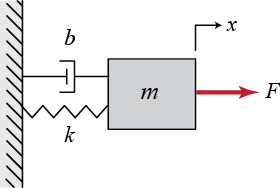

Now we proceed by summing the forces and applying Newton’s second law, in each direction. In this case, there are no forces acting in the$y$-direction; however, in the $x$-direction we have:


$$
\Sigma F_x = F(t) - b \dot{x} - k x = m \ddot{x}
$$


This equation, known as the **governing equation**, completely characterizes the dynamic state of the system.  We can express the avove equation using the state space equation


$$
\mathbf{\dot{x}} = \left[ \begin{array}{c} \dot{x} \\ \ddot{x} \end{array} \right] = \left[ \begin{array}{cc} 0 & 1 \\ -\frac{k}{m}  & -\frac{b}{m} \end{array} \right] \left[ \begin{array}{c} x \\ \dot{x} \end{array} \right] + \left[ \begin{array}{c} 0 \\ \frac{1}{m} \end{array} \right] F(t)
$$


If we are interested in controlling the position of the mass, then the output equation is:


$$
y = \left[ \begin{array}{cc} 1 & 0 \end{array} \right] \left[ \begin{array}{c} x \\ \dot{x} \end{array} \right]
$$


m = 60; 
k = 60; 
b = 20; 
A = [0,1;-k/m,-b/m]; 
B = [0;1/m]; 
C = [1,0]; 
D = 0; 
MSDss = ss(A,B,C,D); 
[x1,x2] = meshgrid(-1.5:.2:1.5,-1.5:.2:1.5);
x1 = x1(:)'; 
x2 = x2(:)'; 
stateSpace = [x1;x2];
stateDiffs = A*stateSpace; 


quiver(x1', x2', stateDiffs(1,:)', stateDiffs(2,:)')
hold on
t = 0:0.1:50; 
[y,tOut,xout] = lsim(MSDss,0*t,t,[1;0]); 
plot(xout(:,1), xout(:,2), 'r')
hold off

Reflect: 

- Change the values of $b$ (the damping coefficient) and observe how the behavior of the system changes. Does the position of the mass go to zero faster when $b$ value increaes? 

- How should the pole locations change when you increase the $b$ value? 

- At what point do you stop seeing oscillations in the position? What should you see in the pole plot at this point? 

- Can we predict when we will stop seeing oscillations? 

figure 
pzplot(MSDss)

## Converting a transfer function to state space representation

In this section, we will explore how to convert a transfer function into its state space representation. 

- State space models are particularly useful in modern control theory, providing a framework that accommodates multiple inputs and outputs and their respective dynamics.

- Switching between frequency domain representation of a system, encapsulated in its transfer function, to its time-domain state space model can be useful. 

**Reflect:**

Before we dive into the specifics, take a moment to think about the general steps required to convert a transfer function into a state space form. 

- What information do you need from the transfer function? 

- How might the order of the transfer function influence the complexity of the resulting state space model?

**Enter you answers here:**

To demonstrate the conversion process, let’s consider a simple transfer function


$$
 \frac{I(s)}{V(s)} = \frac{s}{Ls^2+Rs+\frac{1}{C}}
$$


- First, we will obtain the differential equation for the system using the transfer function  


$$L\ddot{i}(t) + R\dot{i}(t) + \frac{1}{C}i(t) = \dot{v}(t)$$


- We will then select a state vector for the system. For an n-order system, chose all the derivates of order n-1 and lower. 


$$\mathbf{x} = \left[ \begin{array}{c} i \\ \dot{i} \end{array} \right],  \dot{\mathbf{x}} = \left[ \begin{array}{c} \dot{i} \\ \ddot{i} \end{array} \right]$$


- Then, we can write out the state space equations based on the differential equation of the system

% create the state space object using ss() function
L = 100; 
c = 0.01; 
R = 10; 


RLCss2 = NaN; 

% create the transfer function object using tf() function 
RLCtf2 = NaN; 

%use lsim to compare the outputs using the two objects to a sinusoidal input 
t = 0:0.01:5; 
f = 1; 
v = sin(2*pi*f*t); 
vdot = 2*pi*f*cos(2*pi*f*t); 

[y1,tout1] = lsim(RLCss2, vdot,t);
[y2,tout2] = lsim(RLCtf2, v,t);  
plot(tout1,y1, tout2, y2); 
